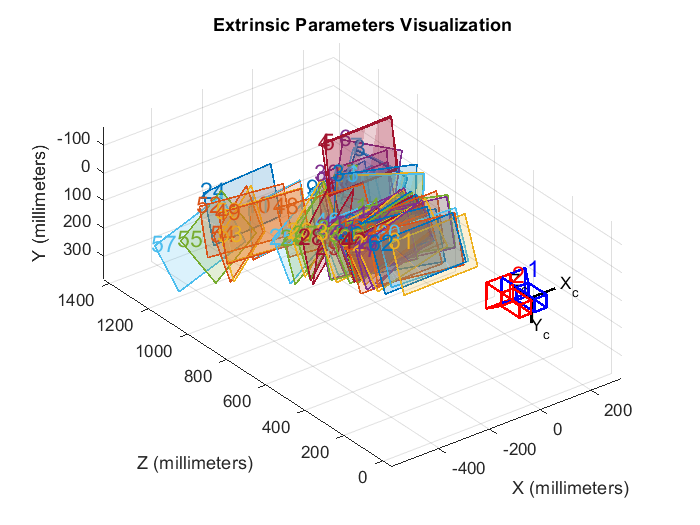

load('stereo_param.mat')

% Visualize camera extrinsics.
showExtrinsics(stereoParams);

I1 = imread('badR4.png');
I2 = imread('badL4.png');

%faceDetector = vision.CascadeObjectDetector;
%face1 = faceDetector(I1)
%face2 = faceDetector(I2)
%------------------------------------
% Read the image into an array.

I1 = undistortImage(I1,stereoParams.CameraParameters1);
I2 = undistortImage(I2,stereoParams.CameraParameters2);

%face1 = [83 62 214-70 143-70]
%face2 = [154 67 285-70 146-70]

%center1 = face1(1:2) + face1(3:4)/2
%center2 = face2(1:2) + face2(3:4)/2
st1 = [117,110]

st1 =    117   110


end1 = [158,132]

end1 =    158   132



st2 = [163,116]

st2 =    163   116


end2 = [203,137]

end2 =    203   137



%center1 = [179 101]
%center2 = [243 108]

center1 = [];
center2 = [];
obj1 = [];
obj2 = [];

for row = st1(1):end1(1)
    for col = st1(2):end1(2)
        center1 = [center1;[row col]];
        obj1 = [obj1 ; [row col 1]];
    end
end

for row = st2(1):end2(1)
    for col = st2(2):end2(2)
        center2 = [center2;[row col]];
        obj2 = [obj2 ; [row col 1]];
    end
end
center1

center1 =    117   110
   117   111
   117   112
   117   113
   117   114
   117   115
   117   116
   117   117
   117   118
   117   119


center2

center2 =    163   116
   163   117
   163   118
   163   119
   163   120
   163   121
   163   122
   163   123
   163   124
   163   125



obj1

obj1 =    117   110     1
   117   111     1
   117   112     1
   117   113     1
   117   114     1
   117   115     1
   117   116     1
   117   117     1
   117   118     1
   117   119     1


obj2

obj2 =    163   116     1
   163   117     1
   163   118     1
   163   119     1
   163   120     1
   163   121     1
   163   122     1
   163   123     1
   163   124     1
   163   125     1


s1 = size(center1);
s2 = size(center2);

if  s1(1)> s2(1)
    min = s2(1);
end
if s1(1)< s2(1)
    min = s1(1);
end

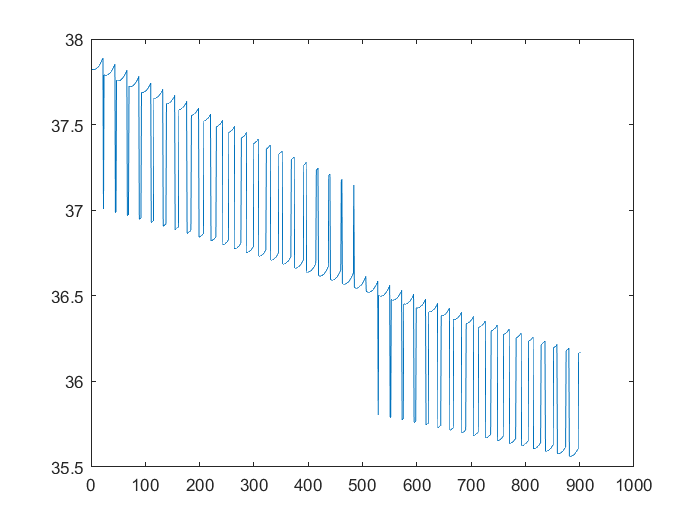

depth_dist = [];
for i = [1:min]
    point3d = triangulate(center1(i,[1,2]), center2(i,[1,2]), stereoParams0);
    %distanceInMeters = norm(point3d)
    distanceInCm = norm(point3d)/10;
    depth_dist = [depth_dist distanceInCm];
end
plot(depth_dist)

depth = mean(depth_dist)

depth = 36.6980


p1 = end1(1)-st1(1)

p1 = 41

p2 = end2(1)-st2(1)

p2 = 40

d = depth;
f1 = 277.5;
f2 = 277.7;
w1 = (p1*d)/f1

w1 = 5.4221

w2 = (p2*d)/f2

w2 = 5.2860

%point3d = triangulate(center1, center2, stereoParams0)
%distanceInMeters = norm(point3d)
%distanceInCm = norm(point3d)/10

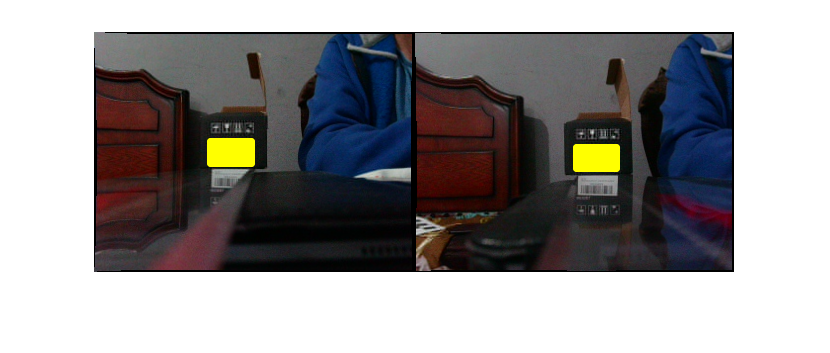

%distanceAsString = sprintf('%0.2f mm', distanceInMeters);
I1 = insertShape(I1,'Circle',obj1,'LineWidth',5);
I2 = insertShape(I2,'Circle',obj2,'LineWidth',5);
 
imshowpair(I1, I2, 'montage');